% Load audio data from file1
file1 = 'Train\S_1.wav';
[data1, fs1] = audioread(file1);

data1 =          0
         0
   -0.0000
         0
         0
         0
         0
   -0.0000
         0
         0


fs1 = 44100

%sound(data1, fs1);
% Load audio data from file2
file2 = 'Train\A_2.wav';
[data2, fs2] = audioread(file2);

data2 =          0
         0
   -0.0000
         0
         0
         0
         0
   -0.0000
         0
         0


fs2 = 44100

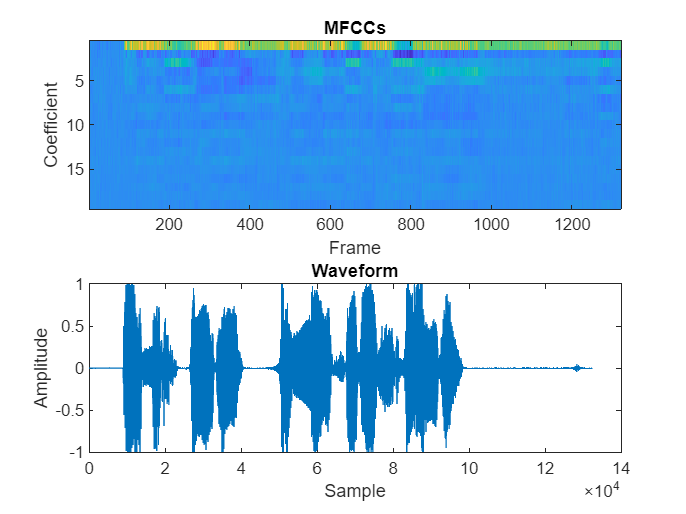

melCeps1 =     0.9664    0.9453   -1.6372   -0.3990   -2.4426   -0.0948    0.7941   -0.2044   -1.1828    0.6533   -0.9171    0.5045   -1.7155   -0.8964    0.3745   -1.1225   -1.2591   -0.6895   -0.3241    0.2038   -0.9240   -2.3912   -0.8017   -1.3669    0.5463   -3.1665   -2.2794   -0.1891   -0.7613   -0.5899    0.7229    0.9645    0.5065   -1.9707   -1.7615    0.2600    0.8080    2.7924    0.4180   -0.9092    0.0438    0.8879    0.9309   -1.8039   -0.3957   -2.5826    0.0911    0.6614   -0.2604   -1.0927
    0.8630    0.1848   -0.4114    1.2935   -0.8730   -0.3284   -0.5800    0.6945   -0.6995   -0.1761   -1.6031   -0.0511   -0.4820   -1.2302   -0.2445   -0.6916   -0.4125    0.5517    0.0207    0.5006   -1.7806   -2.5493    0.0817   -0.8160    0.2127   -1.3217   -1.3105    0.0297   -0.6751    0.2433    0.5680    0.7091    0.6364   -1.2499   -1.7574    0.7954    1.1253    1.2989   -0.1283   -0.3550    0.9932    0.7781    0.1958   -0.4613    1.2608   -1.1085   -0.1403   -0.6591    0.68

%sound(data2, fs1);
% Assuming that both audio files have the same sampling rate
fs = fs1;

% Calculate MFCC Coefficients for file1
melCeps1 = getMFCC(data1, fs1)

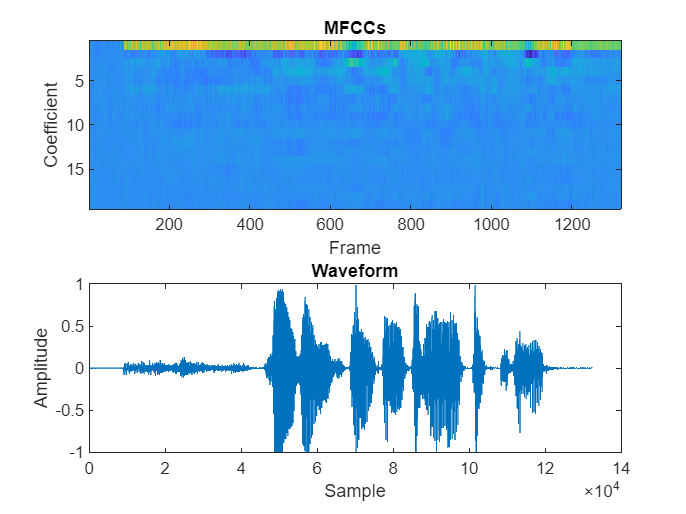

melCeps2 =     0.9664    0.9453   -1.6372   -0.3990   -2.4426   -0.0948    0.7941   -0.2044   -1.1828    0.6533   -0.9171    0.5045   -1.7155   -0.8964    0.3745   -1.1225   -1.2591   -0.6895   -0.3241    0.2038   -0.9240   -2.3912   -0.8017   -1.3669    0.5463   -3.1665   -2.2794   -0.1891   -0.7613   -0.5899    0.7229    0.9645    0.5065   -1.9707   -1.7615    0.2600    0.8080    2.7924    0.4180   -0.9092    0.0438    0.8879    0.9309   -1.8039   -0.3957   -2.5826    0.0911    0.6614   -0.2604   -1.0927
    0.8630    0.1848   -0.4114    1.2935   -0.8730   -0.3284   -0.5800    0.6945   -0.6995   -0.1761   -1.6031   -0.0511   -0.4820   -1.2302   -0.2445   -0.6916   -0.4125    0.5517    0.0207    0.5006   -1.7806   -2.5493    0.0817   -0.8160    0.2127   -1.3217   -1.3105    0.0297   -0.6751    0.2433    0.5680    0.7091    0.6364   -1.2499   -1.7574    0.7954    1.1253    1.2989   -0.1283   -0.3550    0.9932    0.7781    0.1958   -0.4613    1.2608   -1.1085   -0.1403   -0.6591    0.68


% Calculate MFCC Coefficients for file2
melCeps2 = getMFCC(data2, fs2)



% Use DTW to compare the two sets of MFCCs
dist = dtw(melCeps1', melCeps2');

% Print distance between the two audio files
if dist < 1300
    fprintf('Distance between audio files: %f\n', dist);
    fprintf('Access granted.\n');
else
    fprintf('Distance between audio files: %f\n', dist);
    fprintf('Not granted.\n');
end

Distance between audio files: 1451.286126


Not granted.



% Function to calculate MFCCs


function melCeps = getMFCC(data, fs)

% Computing MFCC Co-efficients
N = 256;   % N point FFT
M = 100;   % Overlapping

% Frame Blocking
NN = floor(N/2+1); %N/2
nbFrames = ceil((length(data)-N)/M);
Frames = zeros(nbFrames+1, N);
for i = 0:nbFrames-1
    temp = data(i*M+1:i*M+N);
    Frames(i+1, 1:N) = temp;
end

% Last Frame
temp = zeros(1, N);
lastLength = length(data)-nbFrames*M;
temp(1:lastLength) = data(nbFrames*M+1:(nbFrames*M+1+lastLength-1));
Frames(nbFrames+1, 1:N) = temp;

% Windowing
frameSize = size(Frames);
nbFrames = frameSize(1);
nbSamples = frameSize(2);

% Hamming window
w = hamming(nbSamples);
Windows = zeros(nbFrames, nbSamples);
for i = 1:nbFrames
    temp = Frames(i, 1:nbSamples);
    Windows(i, 1:nbSamples) = w'.*temp;
end

% Fourier Transform
ffts = fft(Windows');

% Mel-frequency Wrapping
% Calculate Power spectrum
PowSpecs = abs(ffts).^2;
PowSpecs = PowSpecs(1:NN-1, :);

% Mel filter generation
nof_c = 20; % Number of channels
df = fs/N;
Nmax = N/2;
fmax = fs/2;

% Convert to mel scale
melmax = 2595*log10(1+fmax/700);
melinc = melmax/(nof_c+1);
melcenters = (1:nof_c).*melinc;

% Convert to frequency scale
fcenters = 700*((10.^(melcenters./2595))-1);
centerf = round(fcenters./df);
startf = [1, centerf(1:nof_c-1)];
stopf = [centerf(2:nof_c), Nmax];

W = zeros(nof_c, Nmax);

% Making filter
for i = 1:nof_c
    increment = 1.0/(centerf(i)-startf(i));
    for j = startf(i):centerf(i)
        W(i, j) = (j-startf(i))*increment;
    end

    decrement = 1.0/(stopf(i)-centerf(i));
    for j = centerf(i):stopf(i)
        W(i, j) = (j-centerf(i))*decrement;
    end
end

% Normalising
for i = 1:nof_c
    W(i, :) = W(i, :)/sum(W(i, :));
end

% Apply mel filters to Power spectrum coeffs
melPowSpecs = W*PowSpecs;

% MFCC calculations
melCeps = dct(log(melPowSpecs));
melCeps(1, :) = [];

% Plotting MFCCs
figure;
subplot(2,1,1);
imagesc(melCeps);
title('MFCCs');
xlabel('Frame');
ylabel('Coefficient');

% Plot the waveform
subplot(2,1,2);
plot(data);
title('Waveform');
xlabel('Sample');
ylabel('Amplitude');

end